# Fitting a model with one set of data and evaluating it with another

e.g., fit the models that generalize across set size (e.g., SlotPlusResourcesModel vs ContinuousResourceModel) using only set sizes 1 and 3, and then ask how well the results generalize to set size 5. 

To facilitate this, the MemToolbox has two functions designed for creating “hold-out” sets of data: GetDataByField() and RemoveDataByField(). For example, if you have a data struct that contains errors from set sizes 1, 3, and 5, and want to fit using only the data from set sizes 1 and 3, you might call:

clear all
% For data from different set sizes
% data.errors = [-10, 2, 43, -2, 1, 100, 119, -34, 11];
% data.n = [1, 1, 1, 3, 3, 3, 5, 5, 5]
% dataWithout5 = RemoveDataByField(data, 'n', 5);
% No good fitting at all

% Use Simulated data from Mixture model
data1=MemDataset(4)

data1 = struct with fields:
       errors: [1×200 double]
    condition: [1×200 double]


data2=MemDataset(5)

data2 = struct with fields:
       errors: [1×200 double]
    condition: [1×200 double]


%fit to get posterior distributions:
StandardMixtureModelSamps = MCMC(data1, StandardMixtureModel);


   Running 3 chains...
   ... not yet converged (200); btw/within variance: 2.01
   ... chains converged after 400 samples!
   ... collecting 6000 samples from converged distribution


VariablePrecisionModelSamps = MCMC(data1, VariablePrecisionModel);


   Running 4 chains...
   ... not yet converged (200); btw/within variance: 2.55
   ... not yet converged (400); btw/within variance: 2.16
   ... not yet converged (600); btw/within variance: 1.87
   ... not yet converged (800); btw/within variance: 1.38
   ... not yet converged (1000); btw/within variance: 1.62
   ... not yet converged (1200); btw/within variance: 1.58
   ... not yet converged (1400); btw/within variance: 1.26
   ... not yet converged (1600); btw/within variance: 1.15
   ... chains converged after 1800 samples!
   ... collecting 6000 samples from converged distribution


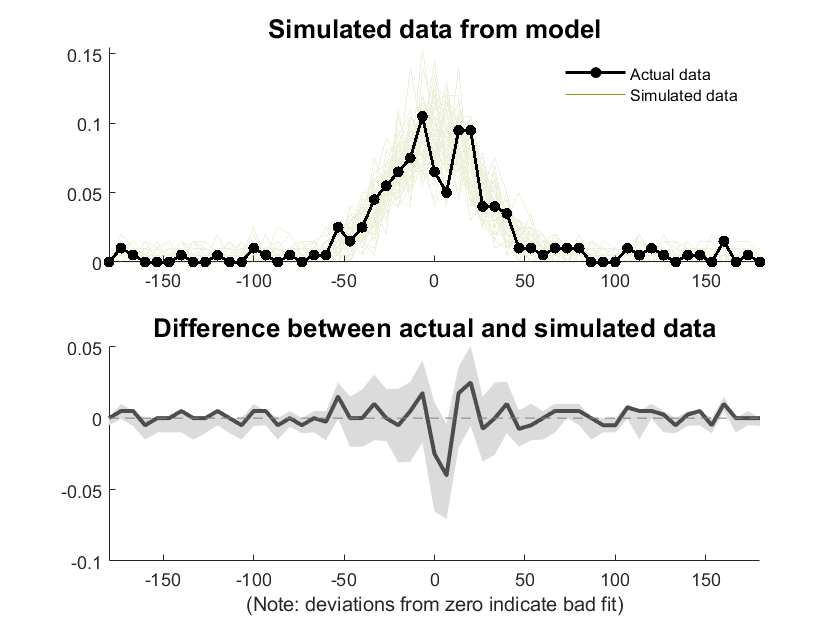


% show a posterior predictive distribution for each model for the data from
% set size 5, to examine which provides a better fit:
% dataSetSize5 = GetDataByField(data, 'n', 5);

PlotPosteriorPredictiveData(StandardMixtureModel, StandardMixtureModelSamps, data2);

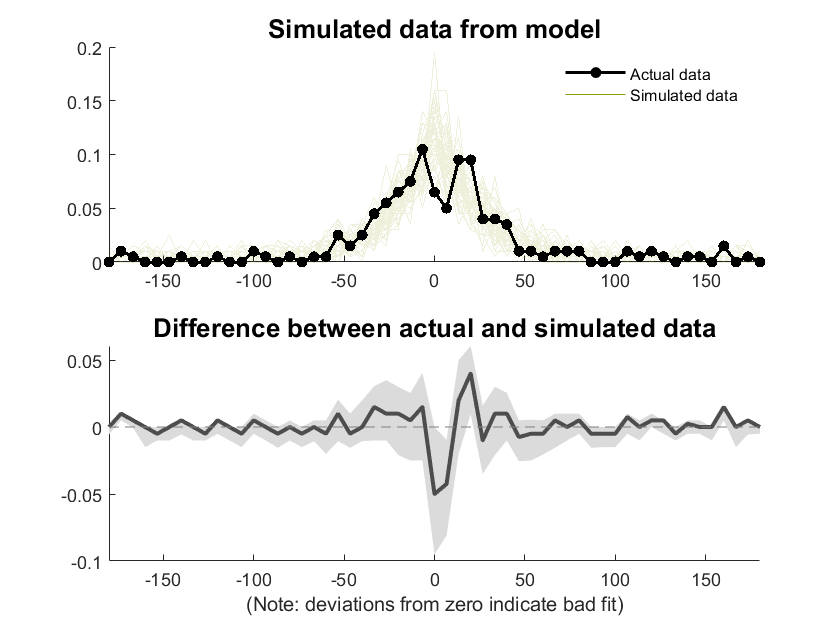

PlotPosteriorPredictiveData(VariablePrecisionModel,VariablePrecisionModelSamps, data2);